Build Map

clear;clc;
% load('scans_12(final).mat');
load('data12f.mat');
scans = scans(1:5:end);

maxRange = 12; % meters
resolution = 20; % cells per meter

slamObj = lidarSLAM(resolution,maxRange);
slamObj.LoopClosureThreshold = 360;
slamObj.LoopClosureSearchRadius = 8;

for i = 1:numel(scans)

    addScan(slamObj,scans{i});
    
    if rem(i,10) == 0
        show(slamObj);
    end
end

[scansSLAM,poses] = scansAndPoses(slamObj);
Map = buildMap(scansSLAM,poses,resolution,maxRange);
figure
show(Map)
title('Occupancy Map')

CAN 통신

scout = canChannel('PEAK-System', 'PCAN_USBBUS1')

다음 사용 중 오류가 발생함: can.peaksystem.pcanbasic.Channel
Unable to obtain driver information for specified device.

오류 발생: canChannel (77번 라인)
        channel = can.peaksystem.pcanbasic.Channel(varargin{:});


start(scout)

message = receive(scout, Inf, "OutputFormat", "timetable")

Table 3.5 Control Mode Setting Frame

TxMsg = canMessage(1057, false, 1);
TxMsg.Data = [1];
transmit(scout,TxMsg)

linear 0.15m/s

TxMsg_linear = canMessage(273, false, 8);
TxMsg_linear.Data = ([255 106 0 0 0 0 0 0]); % 홀수 : 후진/우회전 짝수 : 직진/좌회전
tic
while toc<1
    transmit(scout,TxMsg_linear)
%     rplidar
end

% 37 246 = -2523 (우회전) -> 246 37
% 219 9 = 2523 (좌회전) -> 넣는건 거꾸로 9 219
TxMsg_rotate = canMessage(273, false, 8);
TxMsg_rotate.Data = ([0 0 246 37 0 0 0 0]); % 홀수 : 후진/우회전,  짝수 : 직진/좌회전
tic
while toc<0.5
    transmit(scout,TxMsg_rotate)
%     rplidar
end

% 변환 공식 (거꾸로 넣어야 함)
x = 150
typecast(int16(x), "uint8")

% message = canMessage(273,false,8);
% pack(message,int16(x),0,16,'BigEndian')
% message.Data

% % 0.525초 내에 다음 point로 도달해야 하기 때문에 point를 5배로 늘리기
% xx=[];
% yy=[];
% for i=1:length(poses)-1
%     x = linspace(poses(i, 1),poses(i+1, 1), 6);
%     y = linspace(poses(i, 2),poses(i+1, 2), 6);
%     xx = [xx x(1:end-1)];
%     yy = [yy y(1:end-1)];
% end
% pose = [xx; yy]';

% % point 수를 1/3로 줄이기
% k=3;
% pose = zeros(size(poses(1:k:end,1)));
% pose(:,1) = poses(1:k:end,1);
% pose(:,2) = poses(1:k:end,2);

% 균일한 point를 만들기
path = [0:0.5:7 7*ones(1,24) 6.5:-0.5:-7 -7*ones(1,24) -6.5:0.5:-1;
    zeros(1, 15) 0.5:0.5:12 12*ones(1,28) 11.5:-0.5:0 zeros(1, 12)]'

path =          0         0
    0.5000         0
    1.0000         0
    1.5000         0
    2.0000         0
    2.5000         0
    3.0000         0
    3.5000         0
    4.0000         0
    4.5000         0


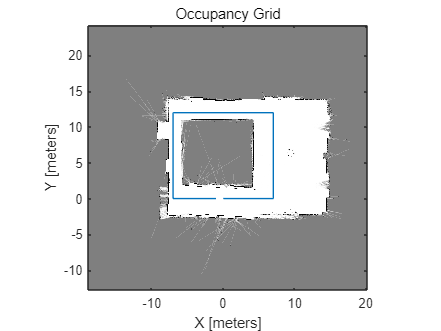

show(Map)
hold on
plot(path(:,1), path(:,2))
hold off

Path following

주요 파라미터 

controller.Waypoints = path; % 간격 일정한게 중요한 듯

controller.LookaheadDistance = 1; % 0.1로 하면 값이 진동

sampleTime = 0.54;

controller.MaxAngularVelocity = 0.2; % 90도만 회전하도록 조정

---------------------------------

robot 파라미터를 scout에 맞게 튜닝 필요했음

% Define Waypoints
% path = poses(:,1:2);
% path = pose;
robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

% Create a Kinematic Robot Model
% robot = differentialDriveKinematics("TrackWidth", 0.4, ...
%     "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
robot = differentialDriveKinematics("TrackWidth", 0.4, ...
    "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
%%%%%%%% VehicleInputs 실험 필요

% figure; plot(path(:,1), path(:,2),'k--d')

% Define the Path Following Controller
controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 0.3;
controller.LookaheadDistance = 1;

% Using the Path Following Controller, Drive the Robot over the Desired Waypoints
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.545;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = 0.4/0.2;
% frameSize = robot.TrackWidth/0.2;

v_vector = [];
omega_vector = [];
i=1;
v_vel = [];
while( distanceToGoal > goalRadius)
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
%     v_vel = [v_vel; vel'];
    v_vector(i) = v*1000;
    omega_vector(i) = omega*1000;
    i=i+1;

    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    axis([-10 10 -5 15])
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", ...
        "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    
    waitfor(vizRate);
end

% %% forward 0.15m/s
% TxMsg_linear = canMessage(273, false, 8);
% TxMsg_linear.Data = ([uint16(v*1000) 0 0 0 0 0 0 0]);
% transmit(scout,TxMsg_linear)

% %% rotate 0.2rad/s
% TxMsg_rotate = canMessage(273, false, 8);
% TxMsg_rotate.Data = ([0 0 0 50 0 0 0 0]);
% transmit(scout,TxMsg_rotate)

% 직선은 0.15m/s 각속도는 그대로 받아서 사용
% linear range : [-3000 3000]
% angular range : [-2523 2523]
% typecast(swapbytes(int16(x)), "uint8")

vv = [];
for i=1:length(v_vector)
    vv{i} = typecast(swapbytes(int16(v_vector(i))), "uint8");
end

ome = [];
for i=1:length(omega_vector)
    ome{i} = typecast(swapbytes(int16(omega_vector(i))), "uint8");
end

% ROTATION 0.54s, length 20, int16(295*0.54) rad/s
sampleTime = 0.545;
vizRate = rateControl(1/sampleTime);
TxMsg = canMessage(273, false, 8);



ans =

  0×0 비어 있는 char 배열



for k=1:length(ome)
    TxMsg.Data = ([vv{k} ome{k} 0 0 0 0]);
%     TxMsg.Data = ([0 0 ome{k} 0 0 0 0]);
    transmit(scout,TxMsg)
    waitfor(vizRate);
end

sampleTime = 0.54;
vizRate = rateControl(1/sampleTime);
TxMsg = canMessage(273, false, 8);

for k=1:length(ome1)
    TxMsg.Data = ([vv{k} ome1{k} 0 0 0 0]);
%     TxMsg.Data = ([0 0 ome{k} 0 0 0 0]);
    transmit(scout,TxMsg)
    waitfor(vizRate);
end

% 각속도에 직선 값 빼기? nope

TxMsg = canMessage(273, false, 8);

tic
for k=1:1
    TxMsg.Data = ([vv{k} ome{k} 0 0 0 0]);
    transmit(scout,TxMsg)
%     waitfor(vizRate);
end
toc

% 1회당 0.545초 굴러감